Dottorro algorithm


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


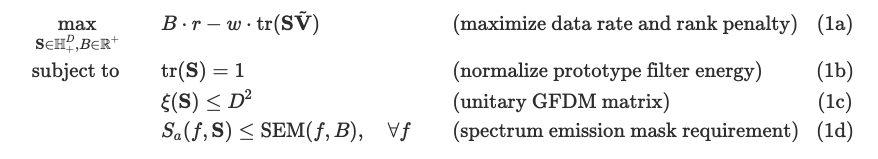

function S = Dottorro(gfdm, B, Channel, P, SEM, f_range, delta_f)
D = gfdm.D;

% Dottorro initialization
s_2 = 1;
V_tilde = zeros(D);
problem_counter = 1;

fprintf('B = %f\n', B);

U_temp = zeros(D, D-1, 25);

% Dottorro loop: solve the optimization problem until the second largest
% singular value is small enough
dottorro_start = tic;
while abs(s_2) > 10^-6
    problem_start = tic;
    cvx_clear
        cvx_begin sdp quiet
        variable S(D, D) hermitian nonnegative semidefinite
        expression psd_temp(length(P), 1)

        % SEM
        switch SEM
            case '802.11ac'
                mask_dB = SEM_ac(delta_f, f_range, B, Channel);
            case '802.11b'
                mask_dB = SEM_b(delta_f, f_range, B, Channel);
        end
        mask_ac_linear = db2pow(mask_dB);
            
        % PSD
        psd = (P.^2) .* PSD_S(gfdm, S, psd_temp, f_range, delta_f);

        minimize trace(S * V_tilde)          % (1a)
        subject to
        trace(S) == 1;                       % (1b)
        nep_S(S, gfdm.K, gfdm.M) <= D^2;     % (1c)
        psd <= mask_ac_linear;               % (1d)

    cvx_end

    % fprintf('Problem time: %s\n', duration([0, 0, toc(problem_start)]));
    try
        [U_svd, S_svd, ~] = svd(S);
    catch ME
    end

    % Break the B increment loop if infeasible
    if isnan(S_svd(1, 1)) || problem_counter>=30
        fprintf('B = %f is INFEASIBLE.\n', B);
        fprintf('Dottorro time: %s\n', duration([0, 0, toc(dottorro_start)]));
        fprintf('===============================\n');
        S = NaN;
        return
    end

    s_2 = S_svd(2, 2);
    fprintf('%d.s_2 = %f\n', problem_counter, s_2);

    U = U_svd(:, 2:end);
    V_tilde = U*U';

    U_temp(:,:,problem_counter) = U;

    problem_counter = problem_counter + 1;
end

fprintf('%B = %f is feasible.\n', B);
fprintf('Dottorro time: %s\n', duration([0, 0, toc(dottorro_start)]));
fprintf('===============================\n');

end